ltfatstart

LTFAT version 2.4.0. Copyright 2005-2018 Peter L. Søndergaard. For help, please type "ltfathelp". LTFAT is using the MEX backend.
(Your global and persistent variables have just been cleared. Sorry.)


files = dir('dataset/*.mp3');
clipping_thrsh = linspace(0.1, 0.9,9);
redundancy_factors = [1, 2, 4];

params.algo = 'sspade';
params.window_length = 1024;
params.hop_length = 512;
            
params.s = 2; % relaxation step size
params.r = 1; % relaxation rate
params.eps = 0.1;
params.max_iter = 5000;

num_files = length(files);
%num_files=1;
num_thresh = length(clipping_thrsh);
num_rf = length(redundancy_factors);

sdr_y = zeros(num_thresh, 1);
sdr_x_hat = zeros(num_thresh, num_rf); 

tic
for k=1:num_files
    disp(['Excerpt ' num2str(k) '/' num2str(num_files)])
    path = ['dataset/' files(k).name];
    disp(path)
    [x, sr] = audioread(path);
    x = resample(x, sr, 16000); % resample to 16kHz
    sr = 16000;
    x = x(1:5*sr,1); % only consider first 5 seconds of 1st channel
    x = x / max(abs(x));
    for ind_thresh=1:num_thresh
        thresh = clipping_thrsh(ind_thresh);
        disp(['Clipping threshold ' num2str(thresh)])
        y = max(-thresh, min(thresh,x)); % clip audio excerpt
        masks.Icp = y == thresh;
        masks.Icm = y == -thresh;
        masks.Ir = ~(masks.Icp | masks.Icm);
        s = sdr(x, y, masks);
        sdr_y(ind_thresh) = sdr_y(ind_thresh) + s;

        for ind_rf=1:num_rf
            rf = redundancy_factors(ind_rf);
            disp(['Redundancy factor ' num2str(rf)])
            
            F = frame('dft');
            F.frana = @(x) redundant_dft(x, rf);
            F.frsyn = @(x) redundant_idft(x, rf);
            
            params.frame = F;
            
            tic
            x_hat = declip(y, params);
            toc
            
            s = sdr(x, x_hat, masks);
            sdr_x_hat(ind_thresh, ind_rf) = sdr_x_hat(ind_thresh, ind_rf) + s;
            disp(['SDR x_hat ' num2str(s)])
            % sanity check
            err_ir = norm(x(masks.Ir) - x_hat(masks.Ir));
            disp(['Error on reliable samples ' num2str(err_ir)])
        end
    end
end

Excerpt 1/10


dataset/000002.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 6.752789 seconds.


SDR x_hat 6.1752


Error on reliable samples 4.4967e-15


Redundancy factor 2


Elapsed time is 7.180319 seconds.


SDR x_hat 5.9226


Error on reliable samples 5.1554e-15


Redundancy factor 4


Elapsed time is 12.773927 seconds.


SDR x_hat 6.065


Error on reliable samples 5.11e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 7.681174 seconds.


SDR x_hat 9.8425


Error on reliable samples 6.3304e-15


Redundancy factor 2


Elapsed time is 7.789704 seconds.


SDR x_hat 9.19


Error on reliable samples 7.0629e-15


Redundancy factor 4


Elapsed time is 12.967561 seconds.


SDR x_hat 9.3331


Error on reliable samples 6.863e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 8.881702 seconds.


SDR x_hat 11.904


Error on reliable samples 7.4055e-15


Redundancy factor 2


Elapsed time is 7.959007 seconds.


SDR x_hat 11.1374


Error on reliable samples 8.1365e-15


Redundancy factor 4


Elapsed time is 13.092963 seconds.


SDR x_hat 11.3542


Error on reliable samples 7.8895e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 8.902640 seconds.


SDR x_hat 11.0882


Error on reliable samples 8.4648e-15


Redundancy factor 2


Elapsed time is 7.789501 seconds.


SDR x_hat 12.2504


Error on reliable samples 9.0362e-15


Redundancy factor 4


Elapsed time is 12.833044 seconds.


SDR x_hat 11.4171


Error on reliable samples 8.9022e-15


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 9.312558 seconds.


SDR x_hat 13.1775


Error on reliable samples 9.2798e-15


Redundancy factor 2


Elapsed time is 7.884605 seconds.


SDR x_hat 13.4063


Error on reliable samples 9.8974e-15


Redundancy factor 4


Elapsed time is 12.842766 seconds.


SDR x_hat 11.5734


Error on reliable samples 9.8046e-15


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 9.556636 seconds.


SDR x_hat 15.2379


Error on reliable samples 9.8803e-15


Redundancy factor 2


Elapsed time is 7.921364 seconds.


SDR x_hat 15.0266


Error on reliable samples 1.0849e-14


Redundancy factor 4


Elapsed time is 12.836128 seconds.


SDR x_hat 14.0854


Error on reliable samples 1.0448e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 9.895114 seconds.


SDR x_hat 16.407


Error on reliable samples 1.0838e-14


Redundancy factor 2


Elapsed time is 7.876786 seconds.


SDR x_hat 16.6208


Error on reliable samples 1.1563e-14


Redundancy factor 4


Elapsed time is 12.845863 seconds.


SDR x_hat 16.4326


Error on reliable samples 1.1237e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 10.166404 seconds.


SDR x_hat 17.1167


Error on reliable samples 1.1238e-14


Redundancy factor 2


Elapsed time is 7.915228 seconds.


SDR x_hat 19.8305


Error on reliable samples 1.2469e-14


Redundancy factor 4


Elapsed time is 12.698916 seconds.


SDR x_hat 17.8486


Error on reliable samples 1.1789e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 10.369919 seconds.


SDR x_hat 17.4229


Error on reliable samples 1.1733e-14


Redundancy factor 2


Elapsed time is 7.966683 seconds.


SDR x_hat 23.0331


Error on reliable samples 1.2848e-14


Redundancy factor 4


Elapsed time is 12.607824 seconds.


SDR x_hat 27.7673


Error on reliable samples 1.1918e-14


Excerpt 2/10


dataset/000010.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 6.921496 seconds.


SDR x_hat 7.8805


Error on reliable samples 5.8976e-15


Redundancy factor 2


Elapsed time is 8.022429 seconds.


SDR x_hat 8.0346


Error on reliable samples 6.5124e-15


Redundancy factor 4


Elapsed time is 14.961193 seconds.


SDR x_hat 7.5736


Error on reliable samples 6.8407e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 9.839616 seconds.


SDR x_hat 11.0681


Error on reliable samples 7.6238e-15


Redundancy factor 2


Elapsed time is 8.688059 seconds.


SDR x_hat 12.0859


Error on reliable samples 8.6765e-15


Redundancy factor 4


Elapsed time is 15.297254 seconds.


SDR x_hat 11.0586


Error on reliable samples 8.7575e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 11.195733 seconds.


SDR x_hat 11.1423


Error on reliable samples 8.6369e-15


Redundancy factor 2


Elapsed time is 8.784240 seconds.


SDR x_hat 10.3234


Error on reliable samples 9.8116e-15


Redundancy factor 4


Elapsed time is 14.219356 seconds.


SDR x_hat 11.6595


Error on reliable samples 9.8617e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 11.419638 seconds.


SDR x_hat 7.2396


Error on reliable samples 9.1121e-15


Redundancy factor 2


Elapsed time is 8.737893 seconds.


SDR x_hat 5.3708


Error on reliable samples 1.0471e-14


Redundancy factor 4


Elapsed time is 14.050447 seconds.


SDR x_hat 5.9718


Error on reliable samples 1.047e-14


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 11.541196 seconds.


SDR x_hat 3.5689


Error on reliable samples 9.3421e-15


Redundancy factor 2


Elapsed time is 8.617876 seconds.


SDR x_hat 2.1168


Error on reliable samples 1.0691e-14


Redundancy factor 4


Elapsed time is 13.820542 seconds.


SDR x_hat 2.7925


Error on reliable samples 1.0706e-14


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 11.336486 seconds.


SDR x_hat 1.2076


Error on reliable samples 9.3615e-15


Redundancy factor 2


Elapsed time is 8.627112 seconds.


SDR x_hat 0.14175


Error on reliable samples 1.0917e-14


Redundancy factor 4


Elapsed time is 13.873598 seconds.


SDR x_hat 2.7748


Error on reliable samples 1.0637e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 11.545711 seconds.


SDR x_hat -0.10253


Error on reliable samples 9.4527e-15


Redundancy factor 2


Elapsed time is 8.666172 seconds.


SDR x_hat -0.64724


Error on reliable samples 1.1031e-14


Redundancy factor 4


Elapsed time is 13.741052 seconds.


SDR x_hat -0.12319


Error on reliable samples 1.0789e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 11.313440 seconds.


SDR x_hat 21.5483


Error on reliable samples 9.158e-15


Redundancy factor 2


Elapsed time is 8.692961 seconds.


SDR x_hat 18.6703


Error on reliable samples 1.0494e-14


Redundancy factor 4


Elapsed time is 13.769846 seconds.


SDR x_hat 18.0643


Error on reliable samples 1.0499e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 11.352567 seconds.


SDR x_hat 45.7973


Error on reliable samples 9.255e-15


Redundancy factor 2


Elapsed time is 8.657542 seconds.


SDR x_hat 42.7748


Error on reliable samples 1.0577e-14


Redundancy factor 4


Elapsed time is 13.709919 seconds.


SDR x_hat 50.7177


Error on reliable samples 1.0522e-14


Excerpt 3/10


dataset/000141.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 3.353693 seconds.


SDR x_hat 9.7946


Error on reliable samples 5.5244e-15


Redundancy factor 2


Elapsed time is 3.185061 seconds.


SDR x_hat 8.7755


Error on reliable samples 5.5693e-15


Redundancy factor 4


Elapsed time is 6.023837 seconds.


SDR x_hat 8.4746


Error on reliable samples 5.3975e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 5.130661 seconds.


SDR x_hat 14.0363


Error on reliable samples 8.4264e-15


Redundancy factor 2


Elapsed time is 3.425339 seconds.


SDR x_hat 13.421


Error on reliable samples 9.1116e-15


Redundancy factor 4


Elapsed time is 6.390260 seconds.


SDR x_hat 13.0041


Error on reliable samples 9.0355e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 6.014827 seconds.


SDR x_hat 15.6501


Error on reliable samples 9.633e-15


Redundancy factor 2


Elapsed time is 3.462648 seconds.


SDR x_hat 14.2063


Error on reliable samples 1.0742e-14


Redundancy factor 4


Elapsed time is 6.493928 seconds.


SDR x_hat 13.8208


Error on reliable samples 1.0652e-14


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 6.457338 seconds.


SDR x_hat 20.5443


Error on reliable samples 1.0316e-14


Redundancy factor 2


Elapsed time is 3.522856 seconds.


SDR x_hat 19.1062


Error on reliable samples 1.1637e-14


Redundancy factor 4


Elapsed time is 6.228555 seconds.


SDR x_hat 18.8477


Error on reliable samples 1.1691e-14


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 6.711808 seconds.


SDR x_hat 21.459


Error on reliable samples 1.0862e-14


Redundancy factor 2


Elapsed time is 3.276308 seconds.


SDR x_hat 17.2924


Error on reliable samples 1.2151e-14


Redundancy factor 4


Elapsed time is 6.031241 seconds.


SDR x_hat 15.0995


Error on reliable samples 1.2535e-14


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 6.850375 seconds.


SDR x_hat 36.9795


Error on reliable samples 1.1298e-14


Redundancy factor 2


Elapsed time is 3.104748 seconds.


SDR x_hat 32.2072


Error on reliable samples 1.2589e-14


Redundancy factor 4


Elapsed time is 5.683485 seconds.


SDR x_hat 36.9595


Error on reliable samples 1.2969e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 6.652869 seconds.


SDR x_hat 47.6413


Error on reliable samples 1.1335e-14


Redundancy factor 2


Elapsed time is 3.165102 seconds.


SDR x_hat 41.9786


Error on reliable samples 1.2822e-14


Redundancy factor 4


Elapsed time is 5.790469 seconds.


SDR x_hat 39.5348


Error on reliable samples 1.3026e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 6.718665 seconds.


SDR x_hat 44.6771


Error on reliable samples 1.1307e-14


Redundancy factor 2


Elapsed time is 3.097505 seconds.


SDR x_hat 41.3763


Error on reliable samples 1.2849e-14


Redundancy factor 4


Elapsed time is 5.615480 seconds.


SDR x_hat 37.328


Error on reliable samples 1.3032e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 6.661931 seconds.


SDR x_hat 50.2613


Error on reliable samples 1.1307e-14


Redundancy factor 2


Elapsed time is 3.154499 seconds.


SDR x_hat 46.0437


Error on reliable samples 1.2851e-14


Redundancy factor 4


Elapsed time is 5.574961 seconds.


SDR x_hat 39.6343


Error on reliable samples 1.3045e-14


Excerpt 4/10


dataset/000182.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 4.959359 seconds.


SDR x_hat 6.9059


Error on reliable samples 7.3555e-15


Redundancy factor 2


Elapsed time is 6.830672 seconds.


SDR x_hat 6.9831


Error on reliable samples 7.6276e-15


Redundancy factor 4


Elapsed time is 13.481257 seconds.


SDR x_hat 7.1436


Error on reliable samples 7.5048e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 6.276107 seconds.


SDR x_hat 8.6395


Error on reliable samples 1.1443e-14


Redundancy factor 2


Elapsed time is 7.727493 seconds.


SDR x_hat 8.6025


Error on reliable samples 1.2614e-14


Redundancy factor 4


Elapsed time is 15.390432 seconds.


SDR x_hat 7.9176


Error on reliable samples 1.2791e-14


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 8.328910 seconds.


SDR x_hat 10.6184


Error on reliable samples 1.3961e-14


Redundancy factor 2


Elapsed time is 7.668252 seconds.


SDR x_hat 10.4845


Error on reliable samples 1.5605e-14


Redundancy factor 4


Elapsed time is 14.913903 seconds.


SDR x_hat 9.4273


Error on reliable samples 1.5698e-14


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 10.502287 seconds.


SDR x_hat 13.0617


Error on reliable samples 1.5743e-14


Redundancy factor 2


Elapsed time is 7.609614 seconds.


SDR x_hat 13.1081


Error on reliable samples 1.7717e-14


Redundancy factor 4


Elapsed time is 14.172251 seconds.


SDR x_hat 12.3176


Error on reliable samples 1.7634e-14


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 12.862267 seconds.


SDR x_hat 15.36


Error on reliable samples 1.711e-14


Redundancy factor 2


Elapsed time is 7.246606 seconds.


SDR x_hat 15.5255


Error on reliable samples 1.9107e-14


Redundancy factor 4


Elapsed time is 13.200160 seconds.


SDR x_hat 13.9606


Error on reliable samples 1.9142e-14


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 13.957193 seconds.


SDR x_hat 17.5297


Error on reliable samples 1.8291e-14


Redundancy factor 2


Elapsed time is 6.934882 seconds.


SDR x_hat 16.8398


Error on reliable samples 2.0456e-14


Redundancy factor 4


Elapsed time is 12.268598 seconds.


SDR x_hat 16.7187


Error on reliable samples 2.0205e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 14.423782 seconds.


SDR x_hat 18.008


Error on reliable samples 1.9017e-14


Redundancy factor 2


Elapsed time is 6.566735 seconds.


SDR x_hat 19.9718


Error on reliable samples 2.1248e-14


Redundancy factor 4


Elapsed time is 11.322049 seconds.


SDR x_hat 20.888


Error on reliable samples 2.1047e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 14.545701 seconds.


SDR x_hat 20.7157


Error on reliable samples 1.9263e-14


Redundancy factor 2


Elapsed time is 6.509517 seconds.


SDR x_hat 22.593


Error on reliable samples 2.1342e-14


Redundancy factor 4


Elapsed time is 10.986268 seconds.


SDR x_hat 21.3347


Error on reliable samples 2.1123e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 14.772321 seconds.


SDR x_hat 22.5132


Error on reliable samples 1.9424e-14


Redundancy factor 2


Elapsed time is 6.315804 seconds.


SDR x_hat 27.7544


Error on reliable samples 2.1424e-14


Redundancy factor 4


Elapsed time is 10.601751 seconds.


SDR x_hat 25.0913


Error on reliable samples 2.1385e-14


Excerpt 5/10


dataset/000193.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 3.989375 seconds.


SDR x_hat 7.5457


Error on reliable samples 6.2378e-15


Redundancy factor 2


Elapsed time is 5.175966 seconds.


SDR x_hat 7.8579


Error on reliable samples 6.1985e-15


Redundancy factor 4


Elapsed time is 9.782701 seconds.


SDR x_hat 8.054


Error on reliable samples 6.0014e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 5.269037 seconds.


SDR x_hat 9.2077


Error on reliable samples 9.6372e-15


Redundancy factor 2


Elapsed time is 5.723318 seconds.


SDR x_hat 9.4214


Error on reliable samples 1.0585e-14


Redundancy factor 4


Elapsed time is 11.304119 seconds.


SDR x_hat 9.5164


Error on reliable samples 1.0508e-14


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 7.149654 seconds.


SDR x_hat 12.9448


Error on reliable samples 1.1432e-14


Redundancy factor 2


Elapsed time is 6.021017 seconds.


SDR x_hat 12.5658


Error on reliable samples 1.2791e-14


Redundancy factor 4


Elapsed time is 11.290480 seconds.


SDR x_hat 12.4819


Error on reliable samples 1.2757e-14


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 8.865299 seconds.


SDR x_hat 16.9369


Error on reliable samples 1.2846e-14


Redundancy factor 2


Elapsed time is 6.087692 seconds.


SDR x_hat 16.9148


Error on reliable samples 1.415e-14


Redundancy factor 4


Elapsed time is 11.131372 seconds.


SDR x_hat 15.764


Error on reliable samples 1.4111e-14


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 9.886827 seconds.


SDR x_hat 21.2445


Error on reliable samples 1.3942e-14


Redundancy factor 2


Elapsed time is 6.250079 seconds.


SDR x_hat 20.3733


Error on reliable samples 1.549e-14


Redundancy factor 4


Elapsed time is 11.499813 seconds.


SDR x_hat 20.6523


Error on reliable samples 1.5357e-14


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 10.427419 seconds.


SDR x_hat 24.3089


Error on reliable samples 1.4638e-14


Redundancy factor 2


Elapsed time is 6.038867 seconds.


SDR x_hat 22.7428


Error on reliable samples 1.6183e-14


Redundancy factor 4


Elapsed time is 10.201595 seconds.


SDR x_hat 23.834


Error on reliable samples 1.6264e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 10.458905 seconds.


SDR x_hat 23.3609


Error on reliable samples 1.5052e-14


Redundancy factor 2


Elapsed time is 5.988181 seconds.


SDR x_hat 26.9389


Error on reliable samples 1.6567e-14


Redundancy factor 4


Elapsed time is 9.980194 seconds.


SDR x_hat 27.6487


Error on reliable samples 1.6661e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 10.575115 seconds.


SDR x_hat 29.0788


Error on reliable samples 1.5176e-14


Redundancy factor 2


Elapsed time is 5.906570 seconds.


SDR x_hat 36.3472


Error on reliable samples 1.6858e-14


Redundancy factor 4


Elapsed time is 9.649282 seconds.


SDR x_hat 39.0572


Error on reliable samples 1.6911e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 10.502211 seconds.


SDR x_hat 27.0862


Error on reliable samples 1.5349e-14


Redundancy factor 2


Elapsed time is 5.826423 seconds.


SDR x_hat 44.9536


Error on reliable samples 1.6943e-14


Redundancy factor 4


Elapsed time is 9.586866 seconds.


SDR x_hat 46.2303


Error on reliable samples 1.6942e-14


Excerpt 6/10


dataset/005157.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 3.537708 seconds.


SDR x_hat 10.2903


Error on reliable samples 2.9198e-15


Redundancy factor 2


Elapsed time is 2.814288 seconds.


SDR x_hat 9.3413


Error on reliable samples 3.2176e-15


Redundancy factor 4


Elapsed time is 5.203158 seconds.


SDR x_hat 9.0376


Error on reliable samples 3.0807e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 3.635943 seconds.


SDR x_hat 9.7548


Error on reliable samples 3.2189e-15


Redundancy factor 2


Elapsed time is 2.869670 seconds.


SDR x_hat 8.8635


Error on reliable samples 3.5977e-15


Redundancy factor 4


Elapsed time is 5.227362 seconds.


SDR x_hat 7.0917


Error on reliable samples 3.4533e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 3.606438 seconds.


SDR x_hat 22.3585


Error on reliable samples 3.2668e-15


Redundancy factor 2


Elapsed time is 2.879746 seconds.


SDR x_hat 14.8106


Error on reliable samples 3.6805e-15


Redundancy factor 4


Elapsed time is 5.221152 seconds.


SDR x_hat 11.7945


Error on reliable samples 3.4828e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 3.734701 seconds.


SDR x_hat 20.7628


Error on reliable samples 3.3077e-15


Redundancy factor 2


Elapsed time is 2.916934 seconds.


SDR x_hat 13.9347


Error on reliable samples 3.7045e-15


Redundancy factor 4


Elapsed time is 5.292028 seconds.


SDR x_hat 16.9805


Error on reliable samples 3.5693e-15


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 3.636516 seconds.


SDR x_hat 34.7195


Error on reliable samples 3.2904e-15


Redundancy factor 2


Elapsed time is 2.900074 seconds.


SDR x_hat 19.2298


Error on reliable samples 3.6879e-15


Redundancy factor 4


Elapsed time is 5.286532 seconds.


SDR x_hat 16.2049


Error on reliable samples 3.5739e-15


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 3.612940 seconds.


SDR x_hat 42.2474


Error on reliable samples 3.2928e-15


Redundancy factor 2


Elapsed time is 2.993146 seconds.


SDR x_hat 23.9184


Error on reliable samples 3.6859e-15


Redundancy factor 4


Elapsed time is 5.126535 seconds.


SDR x_hat 41.248


Error on reliable samples 3.5444e-15


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 3.620817 seconds.


SDR x_hat 47.1797


Error on reliable samples 3.2908e-15


Redundancy factor 2


Elapsed time is 2.859599 seconds.


SDR x_hat 47.9145


Error on reliable samples 3.7e-15


Redundancy factor 4


Elapsed time is 5.097162 seconds.


SDR x_hat 36.5053


Error on reliable samples 3.5839e-15


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 3.699143 seconds.


SDR x_hat 46.1638


Error on reliable samples 3.352e-15


Redundancy factor 2


Elapsed time is 2.918902 seconds.


SDR x_hat 34.2732


Error on reliable samples 3.7683e-15


Redundancy factor 4


Elapsed time is 5.263242 seconds.


SDR x_hat 44.0474


Error on reliable samples 3.546e-15


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 3.693964 seconds.


SDR x_hat 43.8558


Error on reliable samples 3.3017e-15


Redundancy factor 2


Elapsed time is 2.915365 seconds.


SDR x_hat 48.4229


Error on reliable samples 3.7238e-15


Redundancy factor 4


Elapsed time is 5.235872 seconds.


SDR x_hat 43.0846


Error on reliable samples 3.6455e-15


Excerpt 7/10


dataset/005159.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 3.982247 seconds.


SDR x_hat 10.3766


Error on reliable samples 4.2395e-15


Redundancy factor 2


Elapsed time is 2.911709 seconds.


SDR x_hat 10.2221


Error on reliable samples 4.3122e-15


Redundancy factor 4


Elapsed time is 5.485471 seconds.


SDR x_hat 10.2353


Error on reliable samples 4.1549e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 6.647053 seconds.


SDR x_hat 13.0687


Error on reliable samples 6.4495e-15


Redundancy factor 2


Elapsed time is 3.227914 seconds.


SDR x_hat 13.5289


Error on reliable samples 6.812e-15


Redundancy factor 4


Elapsed time is 5.902364 seconds.


SDR x_hat 13.5471


Error on reliable samples 6.5281e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 7.201189 seconds.


SDR x_hat 21.3478


Error on reliable samples 7.1351e-15


Redundancy factor 2


Elapsed time is 3.361552 seconds.


SDR x_hat 10.5867


Error on reliable samples 7.5482e-15


Redundancy factor 4


Elapsed time is 5.797458 seconds.


SDR x_hat 16.3698


Error on reliable samples 7.3357e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 7.168482 seconds.


SDR x_hat 17.6646


Error on reliable samples 7.2263e-15


Redundancy factor 2


Elapsed time is 3.305988 seconds.


SDR x_hat 17.0193


Error on reliable samples 7.6689e-15


Redundancy factor 4


Elapsed time is 5.889390 seconds.


SDR x_hat 18.3257


Error on reliable samples 7.4701e-15


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 7.135104 seconds.


SDR x_hat 14.6765


Error on reliable samples 7.2405e-15


Redundancy factor 2


Elapsed time is 3.363943 seconds.


SDR x_hat 13.4941


Error on reliable samples 7.7311e-15


Redundancy factor 4


Elapsed time is 5.815076 seconds.


SDR x_hat 16.7734


Error on reliable samples 7.48e-15


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 7.085334 seconds.


SDR x_hat 18.3778


Error on reliable samples 7.2422e-15


Redundancy factor 2


Elapsed time is 3.344109 seconds.


SDR x_hat 15.2939


Error on reliable samples 7.6871e-15


Redundancy factor 4


Elapsed time is 5.789424 seconds.


SDR x_hat 12.6954


Error on reliable samples 7.4921e-15


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 7.151112 seconds.


SDR x_hat 18.0724


Error on reliable samples 7.2351e-15


Redundancy factor 2


Elapsed time is 3.371801 seconds.


SDR x_hat 17.1611


Error on reliable samples 7.7119e-15


Redundancy factor 4


Elapsed time is 6.284065 seconds.


SDR x_hat 16.5662


Error on reliable samples 7.4848e-15


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 7.131429 seconds.


SDR x_hat 17.3821


Error on reliable samples 7.2509e-15


Redundancy factor 2


Elapsed time is 3.314953 seconds.


SDR x_hat 15.45


Error on reliable samples 7.7075e-15


Redundancy factor 4


Elapsed time is 5.941269 seconds.


SDR x_hat 15.8365


Error on reliable samples 7.595e-15


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 8.362779 seconds.


SDR x_hat 16.4535


Error on reliable samples 7.2659e-15


Redundancy factor 2


Elapsed time is 3.830466 seconds.


SDR x_hat 15.2372


Error on reliable samples 7.7192e-15


Redundancy factor 4


Elapsed time is 6.703012 seconds.


SDR x_hat 16.0303


Error on reliable samples 7.4764e-15


Excerpt 8/10


dataset/005170.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 2.952028 seconds.


SDR x_hat 6.739


Error on reliable samples 2.6315e-15


Redundancy factor 2


Elapsed time is 2.404251 seconds.


SDR x_hat 6.4443


Error on reliable samples 2.8852e-15


Redundancy factor 4


Elapsed time is 4.411514 seconds.


SDR x_hat 5.7988


Error on reliable samples 2.8049e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 2.935051 seconds.


SDR x_hat 7.4849


Error on reliable samples 2.7614e-15


Redundancy factor 2


Elapsed time is 2.386804 seconds.


SDR x_hat 7.2701


Error on reliable samples 3.0721e-15


Redundancy factor 4


Elapsed time is 4.519781 seconds.


SDR x_hat 6.3778


Error on reliable samples 3.0012e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 2.930298 seconds.


SDR x_hat 20.0521


Error on reliable samples 2.7928e-15


Redundancy factor 2


Elapsed time is 2.311848 seconds.


SDR x_hat 15.8939


Error on reliable samples 3.161e-15


Redundancy factor 4


Elapsed time is 4.364282 seconds.


SDR x_hat 17.2947


Error on reliable samples 3.1149e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 2.934426 seconds.


SDR x_hat 26.0992


Error on reliable samples 2.8546e-15


Redundancy factor 2


Elapsed time is 2.303616 seconds.


SDR x_hat 25.6383


Error on reliable samples 3.2144e-15


Redundancy factor 4


Elapsed time is 4.364867 seconds.


SDR x_hat 24.9667


Error on reliable samples 3.0973e-15


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 2.934837 seconds.


SDR x_hat 26.2988


Error on reliable samples 2.8832e-15


Redundancy factor 2


Elapsed time is 2.272042 seconds.


SDR x_hat 16.0154


Error on reliable samples 3.2961e-15


Redundancy factor 4


Elapsed time is 4.228818 seconds.


SDR x_hat 14.6903


Error on reliable samples 3.1919e-15


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 2.923522 seconds.


SDR x_hat 42.6041


Error on reliable samples 2.8779e-15


Redundancy factor 2


Elapsed time is 2.323899 seconds.


SDR x_hat 25.0641


Error on reliable samples 3.2347e-15


Redundancy factor 4


Elapsed time is 4.305622 seconds.


SDR x_hat 19.4063


Error on reliable samples 3.1978e-15


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 2.857457 seconds.


SDR x_hat 47.0854


Error on reliable samples 2.8695e-15


Redundancy factor 2


Elapsed time is 2.241181 seconds.


SDR x_hat 37.0325


Error on reliable samples 3.2979e-15


Redundancy factor 4


Elapsed time is 4.297239 seconds.


SDR x_hat 28.6654


Error on reliable samples 3.1611e-15


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 2.967082 seconds.


SDR x_hat 43.7603


Error on reliable samples 2.8775e-15


Redundancy factor 2


Elapsed time is 2.319100 seconds.


SDR x_hat 38.5249


Error on reliable samples 3.3017e-15


Redundancy factor 4


Elapsed time is 4.317749 seconds.


SDR x_hat 33.1248


Error on reliable samples 3.2455e-15


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 2.910599 seconds.


SDR x_hat 42.8385


Error on reliable samples 2.9153e-15


Redundancy factor 2


Elapsed time is 2.264388 seconds.


SDR x_hat 48.1246


Error on reliable samples 3.282e-15


Redundancy factor 4


Elapsed time is 4.372651 seconds.


SDR x_hat 36.1723


Error on reliable samples 3.2548e-15


Excerpt 9/10


dataset/005191.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 5.834909 seconds.


SDR x_hat 7.5676


Error on reliable samples 6.6365e-15


Redundancy factor 2


Elapsed time is 7.440302 seconds.


SDR x_hat 7.5271


Error on reliable samples 7.2539e-15


Redundancy factor 4


Elapsed time is 14.647331 seconds.


SDR x_hat 7.5478


Error on reliable samples 7.3513e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 8.363478 seconds.


SDR x_hat 9.7318


Error on reliable samples 9.3095e-15


Redundancy factor 2


Elapsed time is 7.937327 seconds.


SDR x_hat 9.8785


Error on reliable samples 1.0483e-14


Redundancy factor 4


Elapsed time is 15.041316 seconds.


SDR x_hat 9.7113


Error on reliable samples 1.068e-14


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 10.092566 seconds.


SDR x_hat 12.4678


Error on reliable samples 1.0678e-14


Redundancy factor 2


Elapsed time is 8.352625 seconds.


SDR x_hat 11.7239


Error on reliable samples 1.2113e-14


Redundancy factor 4


Elapsed time is 14.789886 seconds.


SDR x_hat 12.4042


Error on reliable samples 1.2308e-14


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 11.260337 seconds.


SDR x_hat 14.2229


Error on reliable samples 1.1773e-14


Redundancy factor 2


Elapsed time is 8.158292 seconds.


SDR x_hat 14.2141


Error on reliable samples 1.3358e-14


Redundancy factor 4


Elapsed time is 13.830754 seconds.


SDR x_hat 14.099


Error on reliable samples 1.3524e-14


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 11.796644 seconds.


SDR x_hat 17.3949


Error on reliable samples 1.2298e-14


Redundancy factor 2


Elapsed time is 8.044139 seconds.


SDR x_hat 17.9575


Error on reliable samples 1.3926e-14


Redundancy factor 4


Elapsed time is 13.953553 seconds.


SDR x_hat 20.0936


Error on reliable samples 1.41e-14


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 12.183458 seconds.


SDR x_hat 20.1907


Error on reliable samples 1.2856e-14


Redundancy factor 2


Elapsed time is 8.076640 seconds.


SDR x_hat 21.2827


Error on reliable samples 1.4665e-14


Redundancy factor 4


Elapsed time is 13.359271 seconds.


SDR x_hat 21.804


Error on reliable samples 1.4437e-14


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 12.135203 seconds.


SDR x_hat 25.1505


Error on reliable samples 1.2957e-14


Redundancy factor 2


Elapsed time is 7.924237 seconds.


SDR x_hat 23.0686


Error on reliable samples 1.4881e-14


Redundancy factor 4


Elapsed time is 13.174347 seconds.


SDR x_hat 25.064


Error on reliable samples 1.4808e-14


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 12.457380 seconds.


SDR x_hat 25.9192


Error on reliable samples 1.2986e-14


Redundancy factor 2


Elapsed time is 7.965850 seconds.


SDR x_hat 24.2817


Error on reliable samples 1.488e-14


Redundancy factor 4


Elapsed time is 12.935505 seconds.


SDR x_hat 28.8904


Error on reliable samples 1.4822e-14


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 12.202917 seconds.


SDR x_hat 35.8588


Error on reliable samples 1.3044e-14


Redundancy factor 2


Elapsed time is 7.864542 seconds.


SDR x_hat 38.7116


Error on reliable samples 1.495e-14


Redundancy factor 4


Elapsed time is 13.014410 seconds.


SDR x_hat 35.2023


Error on reliable samples 1.4866e-14


Excerpt 10/10


dataset/094803.mp3


Clipping threshold 0.1


Redundancy factor 1


Elapsed time is 6.498392 seconds.


SDR x_hat 7.2566


Error on reliable samples 4.6909e-15


Redundancy factor 2


Elapsed time is 7.177884 seconds.


SDR x_hat 7.1705


Error on reliable samples 4.774e-15


Redundancy factor 4


Elapsed time is 13.113488 seconds.


SDR x_hat 7.2104


Error on reliable samples 4.6287e-15


Clipping threshold 0.2


Redundancy factor 1


Elapsed time is 10.075162 seconds.


SDR x_hat 10.6699


Error on reliable samples 6.6491e-15


Redundancy factor 2


Elapsed time is 9.457135 seconds.


SDR x_hat 10.7814


Error on reliable samples 7.0646e-15


Redundancy factor 4


Elapsed time is 15.991001 seconds.


SDR x_hat 10.9435


Error on reliable samples 6.7986e-15


Clipping threshold 0.3


Redundancy factor 1


Elapsed time is 11.291631 seconds.


SDR x_hat 14.9694


Error on reliable samples 7.2943e-15


Redundancy factor 2


Elapsed time is 9.980278 seconds.


SDR x_hat 14.6306


Error on reliable samples 7.8975e-15


Redundancy factor 4


Elapsed time is 16.207311 seconds.


SDR x_hat 13.9811


Error on reliable samples 7.5425e-15


Clipping threshold 0.4


Redundancy factor 1


Elapsed time is 11.485183 seconds.


SDR x_hat 14.7409


Error on reliable samples 7.4937e-15


Redundancy factor 2


Elapsed time is 10.000086 seconds.


SDR x_hat 24.1081


Error on reliable samples 8.1743e-15


Redundancy factor 4


Elapsed time is 16.845881 seconds.


SDR x_hat 21.6649


Error on reliable samples 7.7643e-15


Clipping threshold 0.5


Redundancy factor 1


Elapsed time is 11.786388 seconds.


SDR x_hat 40.3234


Error on reliable samples 7.5159e-15


Redundancy factor 2


Elapsed time is 10.110987 seconds.


SDR x_hat 43.4851


Error on reliable samples 8.1775e-15


Redundancy factor 4


Elapsed time is 16.406369 seconds.


SDR x_hat 39.7807


Error on reliable samples 7.8119e-15


Clipping threshold 0.6


Redundancy factor 1


Elapsed time is 11.386596 seconds.


SDR x_hat 44.9388


Error on reliable samples 7.5133e-15


Redundancy factor 2


Elapsed time is 10.009641 seconds.


SDR x_hat 40.5748


Error on reliable samples 8.185e-15


Redundancy factor 4


Elapsed time is 16.657624 seconds.


SDR x_hat 33.2466


Error on reliable samples 7.8176e-15


Clipping threshold 0.7


Redundancy factor 1


Elapsed time is 11.467395 seconds.


SDR x_hat 45.0848


Error on reliable samples 7.5177e-15


Redundancy factor 2


Elapsed time is 10.145587 seconds.


SDR x_hat 39.6988


Error on reliable samples 8.1797e-15


Redundancy factor 4


Elapsed time is 16.025144 seconds.


SDR x_hat 48.6794


Error on reliable samples 7.8101e-15


Clipping threshold 0.8


Redundancy factor 1


Elapsed time is 11.170734 seconds.


SDR x_hat 36.4604


Error on reliable samples 7.5167e-15


Redundancy factor 2


Elapsed time is 9.563948 seconds.


SDR x_hat 44.3405


Error on reliable samples 8.1839e-15


Redundancy factor 4


Elapsed time is 15.157711 seconds.


SDR x_hat 42.0847


Error on reliable samples 7.8115e-15


Clipping threshold 0.9


Redundancy factor 1


Elapsed time is 10.898910 seconds.


SDR x_hat 57.6388


Error on reliable samples 7.5121e-15


Redundancy factor 2


Elapsed time is 9.681629 seconds.


SDR x_hat 49.23


Error on reliable samples 8.2039e-15


Redundancy factor 4


Elapsed time is 14.941693 seconds.


SDR x_hat 47.201


Error on reliable samples 7.8067e-15


toc

Elapsed time is 14.948434 seconds.



sdr_x_hat = sdr_x_hat / num_files;
sdr_y = sdr_y / num_files;

if strcmp(params.algo, 'aspade')
    sdr_x_hat_aspade = sdr_x_hat;
elseif strcmp(params.algo, 'sspade')
    sdr_x_hat_sspade = sdr_x_hat;
end

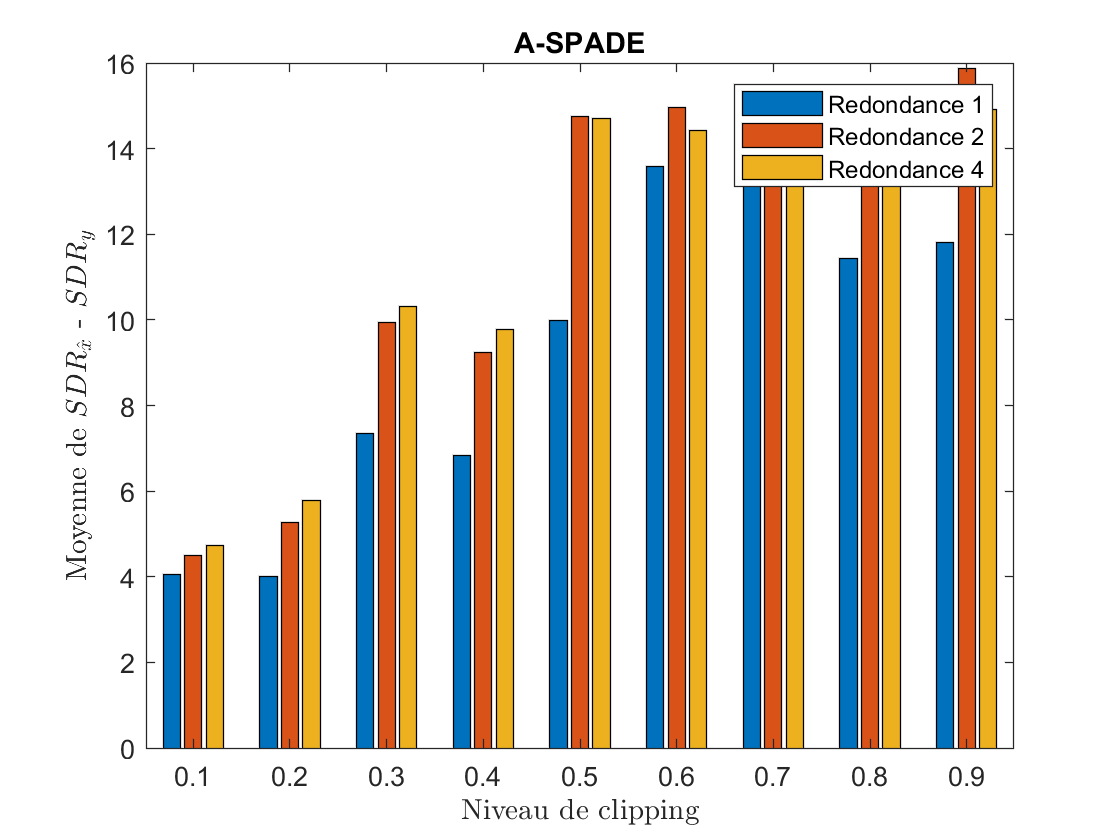

figure;
bar(clipping_thrsh, sdr_x_hat_aspade - sdr_y);
legend('Redondance 1', 'Redondance 2', 'Redondance 4')
title('A-SPADE')
xlabel('Niveau de clipping', 'Interpreter', 'Latex')
ylabel('Moyenne de $SDR_{\hat{x}}$ - $SDR_y$', 'Interpreter', 'Latex')

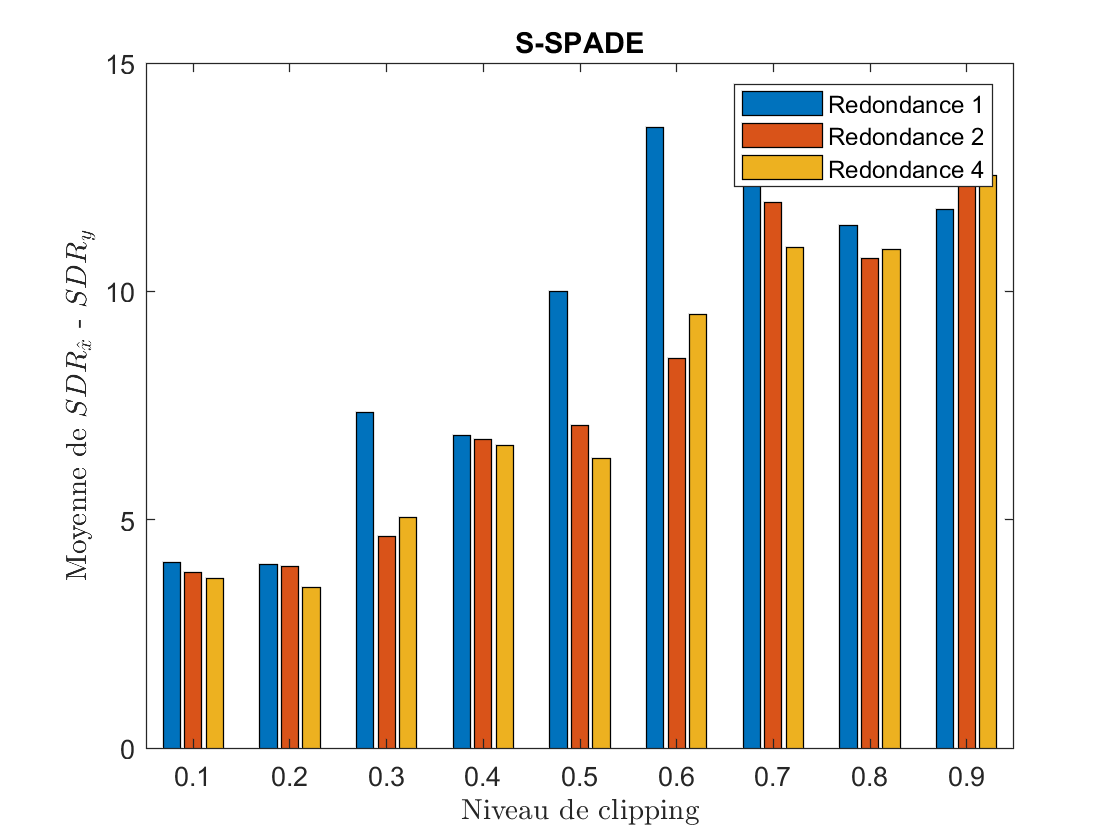

Excerpt 1/21


dataset/000002.mp3


Excerpt 2/21


dataset/000005.mp3


Excerpt 3/21


dataset/000010.mp3


Excerpt 4/21


dataset/000140.mp3


Excerpt 5/21


dataset/000141.mp3


Excerpt 6/21


dataset/000148.mp3


Excerpt 7/21


dataset/000182.mp3


Excerpt 8/21


dataset/000190.mp3


Excerpt 9/21


dataset/000193.mp3


Excerpt 10/21


dataset/000194.mp3


Excerpt 11/21


dataset/005157.mp3


Excerpt 12/21


dataset/005158.mp3


Excerpt 13/21


dataset/005159.mp3


Excerpt 14/21


dataset/005169.mp3


Excerpt 15/21


dataset/005170.mp3


Excerpt 16/21


dataset/005171.mp3


Excerpt 17/21


dataset/005191.mp3


Excerpt 18/21


dataset/005264.mp3


Excerpt 19/21


dataset/005268.mp3


Excerpt 20/21


dataset/005376.mp3


Excerpt 21/21


dataset/094803.mp3


figure;
bar(clipping_thrsh, sdr_x_hat_sspade - sdr_y);
legend('Redondance 1', 'Redondance 2', 'Redondance 4')
title('S-SPADE')
xlabel('Niveau de clipping', 'Interpreter', 'Latex')
ylabel('Moyenne de $SDR_{\hat{x}}$ - $SDR_y$', 'Interpreter', 'Latex')